clear; clc; close all;

%Load signals
edfFilename = 'R1.edf';
[~, record1] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


edfFilename = 'R2.edf';
[~, record2] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


edfFilename = 'R3.edf';
[~, record3] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


edfFilename = 'R4.edf';
[~, record4] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


edfFilename = 'R5.edf';
[~, record5] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


## Get all segements of the signals

ECG_R1 = record1(4, 1:length(record1));
ECG_R1 = ECG_R1';
ECG_R2 = record2(4, 1:length(record2)); 
ECG_R2 = ECG_R2';
ECG_R3 = record3(4, 1:length(record3)); 
ECG_R3 = ECG_R3';
ECG_R4 = record4(4, 1:length(record4)); 
ECG_R4 = ECG_R4';
ECG_R5 = record5(4, 1:length(record5)); 
ECG_R5 = ECG_R5';

## Preprocessing

preprocessed_R1 = preprocess(ECG_R1);
preprocessed_R2 = preprocess(ECG_R2);
preprocessed_R3 = preprocess(ECG_R3);
preprocessed_R4 = preprocess(ECG_R4);
preprocessed_R5 = preprocess(ECG_R5);

## Arrange dataset

epoch_R1 = arrangeDataECG(preprocessed_R1); 
epoch_R2 = arrangeDataECG(preprocessed_R2); 
epoch_R3 = arrangeDataECG(preprocessed_R3);
epoch_R4 = arrangeDataECG(preprocessed_R4);
epoch_R5 = arrangeDataECG(preprocessed_R5);

%Number of samples for each recording
nSamples = [height(epoch_R1);height(epoch_R2);height(epoch_R3);...
    height(epoch_R4);height(epoch_R5)];

## Get RR intervals

RRInterval_R1 = findRRinterval(epoch_R1, height(epoch_R1));
RRInterval_R2 = findRRinterval(epoch_R2, height(epoch_R2));
RRInterval_R3 = findRRinterval(epoch_R3, height(epoch_R3));
RRInterval_R4 = findRRinterval(epoch_R4, height(epoch_R4));
RRInterval_R5 = findRRinterval(epoch_R5, height(epoch_R5));

## Extract features

hrv_R1 = extractFeaturesECG(RRInterval_R1);
hrv_R2 = extractFeaturesECG(RRInterval_R2);
hrv_R3 = extractFeaturesECG(RRInterval_R3);
hrv_R4 = extractFeaturesECG(RRInterval_R4);
hrv_R5 = extractFeaturesECG(RRInterval_R5);
hrv = [hrv_R1;hrv_R2;hrv_R3;hrv_R4;hrv_R5]; %feature matrix
hrv_norm = normalize(hrv); %normalize features

## Statistical check

corrcoef(hrv_norm,hrv)

ans =     1.0000    0.2017
    0.2017    1.0000


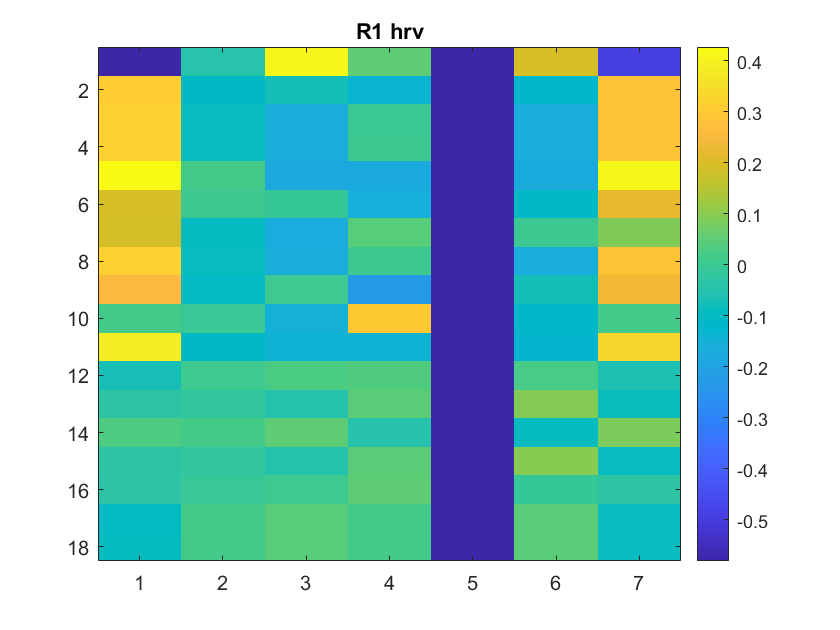

%R1
taskf('R1.xml', hrv(1:1083,:), 'R1 hrv');

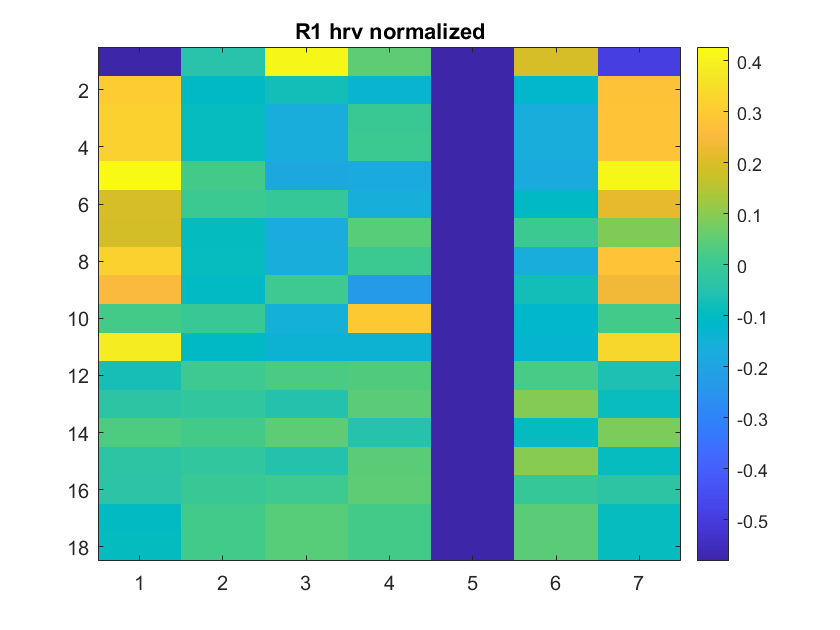

taskf('R1.xml', hrv_norm(1:1083,:),'R1 hrv normalized');

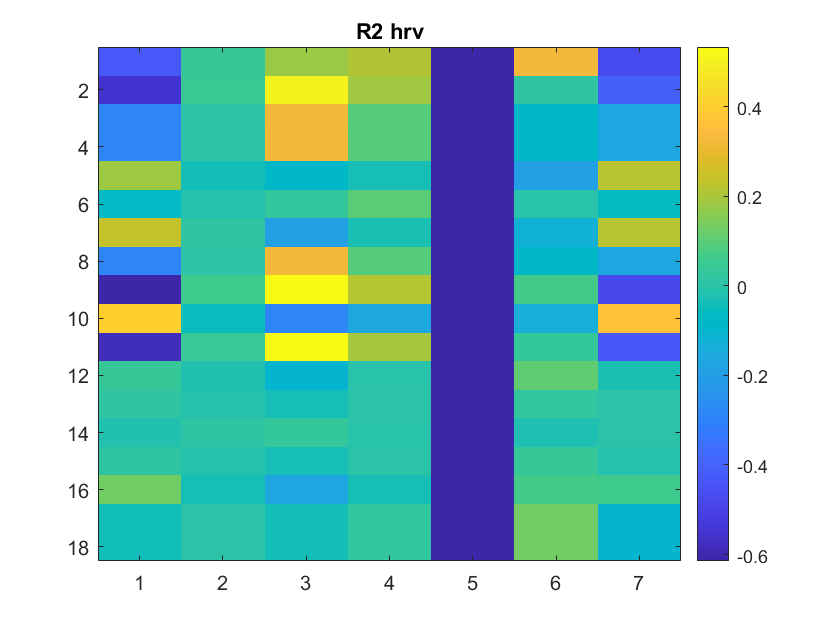

%R2
taskf('R2.xml', hrv(1084:2161,:),'R2 hrv');

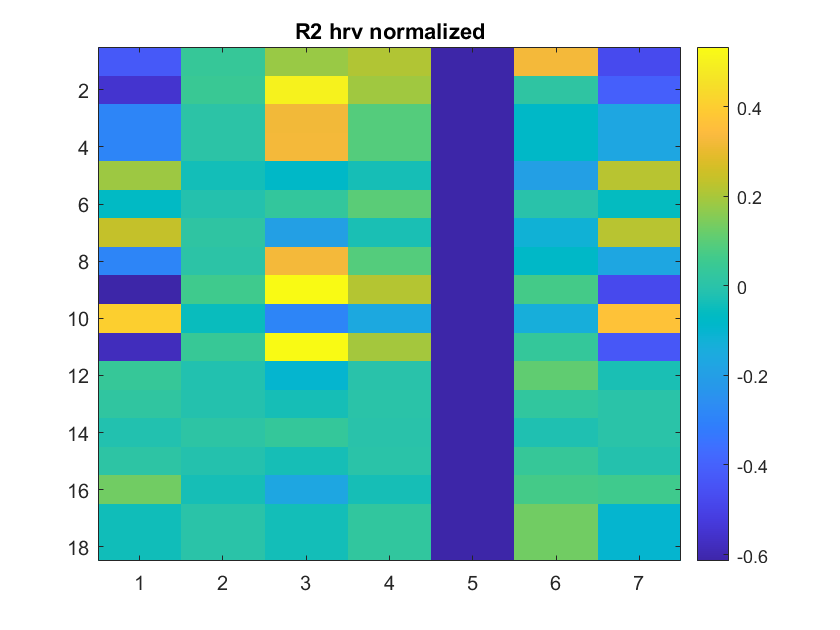

taskf('R2.xml', hrv_norm(1084:2161,:),'R2 hrv normalized');

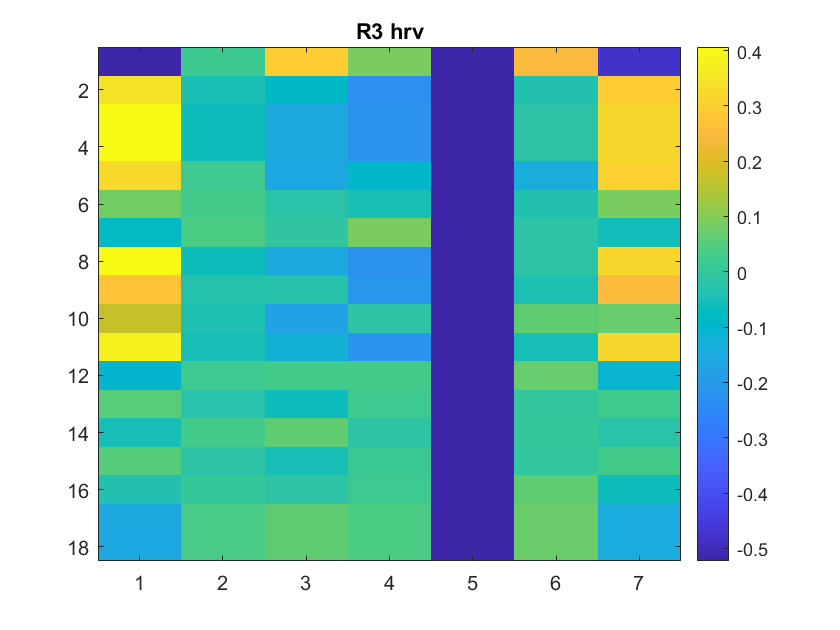

%R3
taskf('R3.xml', hrv(2162:3209,:),'R3 hrv');

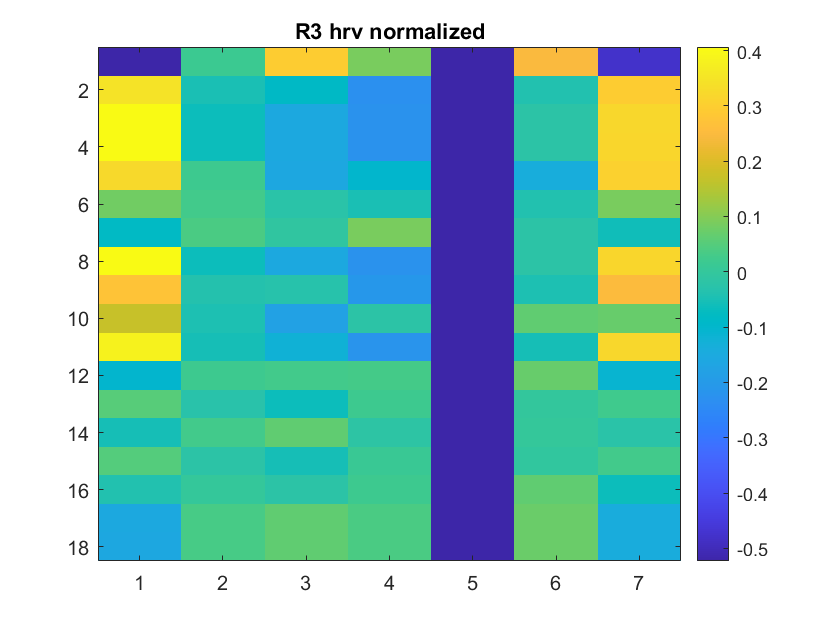

taskf('R3.xml', hrv_norm(2162:3209,:),'R3 hrv normalized');

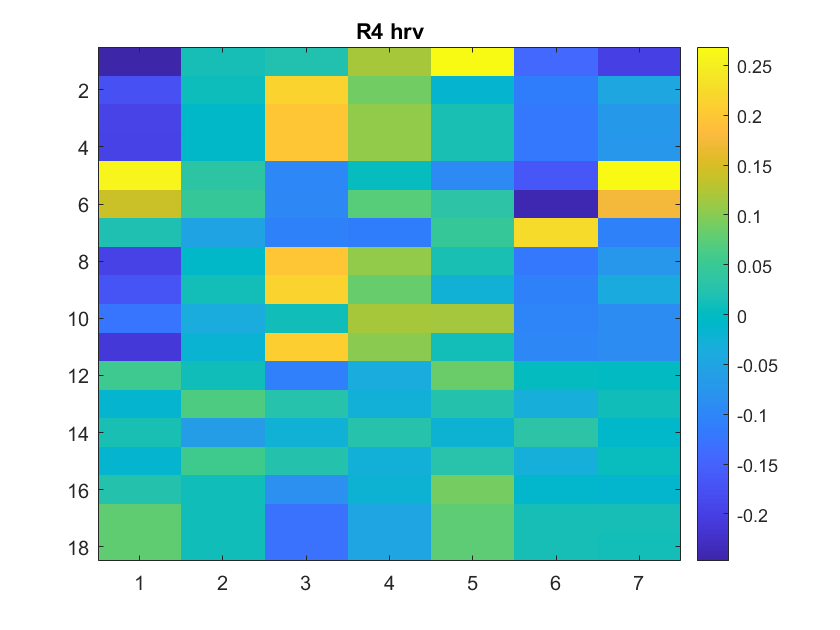

%R4
taskf('R4.xml', hrv(3210:4083,:), 'R4 hrv');

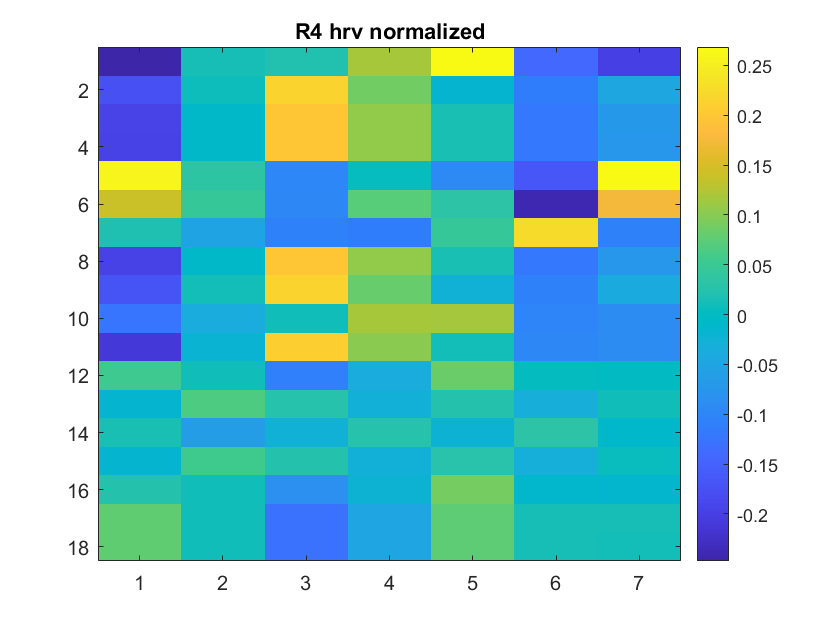

taskf('R4.xml', hrv_norm(3210:4083,:),'R4 hrv normalized');

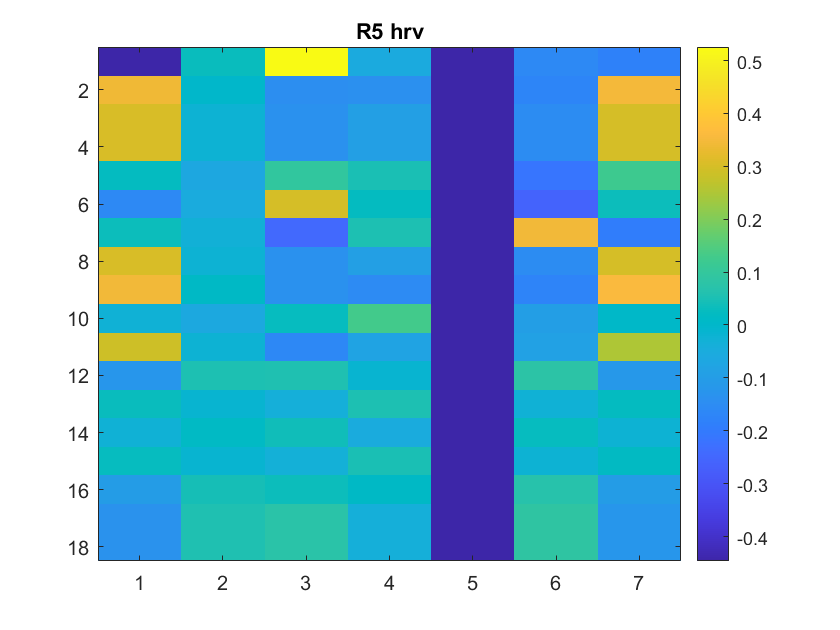

%R5
taskf('R5.xml', hrv(4084:5166,:),'R5 hrv');

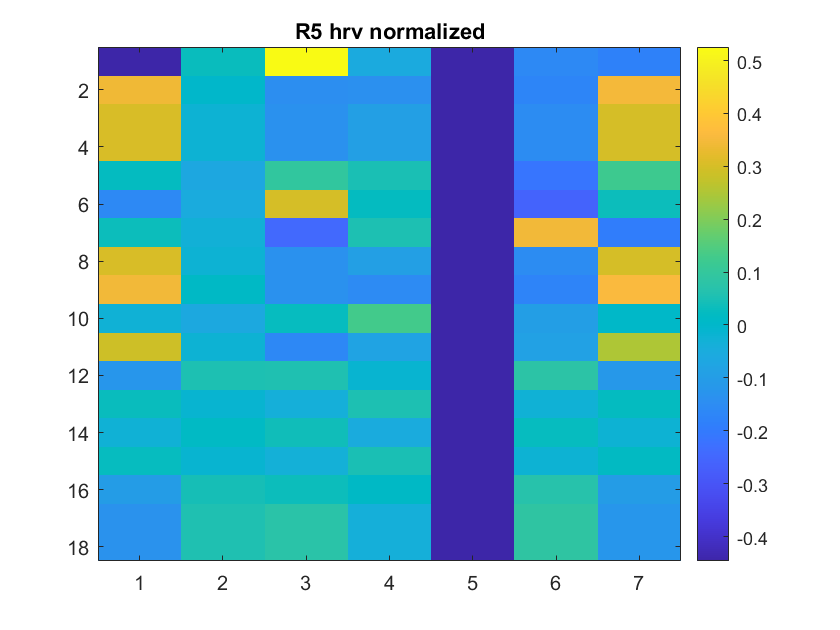

taskf('R5.xml', hrv_norm(4084:5166,:),'R5 hrv normalized');

## Save features as xlsx file

saveFeaturesECG(hrv, 'hrv_features.xlsx'); saveFeaturesECG(hrv_norm, 'hrv_norm_features.xlsx');

## Load and arrange stages

[~, stages_R1, ~, ~] = readXML('R1.xml');
[~, stages_R2, ~, ~] = readXML('R2.xml');
[~, stages_R3, ~, ~] = readXML('R3.xml');
[~, stages_R4, ~, ~] = readXML('R4.xml');
[~, stages_R5, ~, ~] = readXML('R5.xml');

stages_R1 = reshape(stages_R1, 30, []);
stages_R1 = stages_R1';
stages_R2 = reshape(stages_R2, 30, []);
stages_R2 = stages_R2';
stages_R3 = reshape(stages_R3, 30, []);
stages_R3 = stages_R3';
stages_R4 = reshape(stages_R4, 30, []);
stages_R4 = stages_R4';
stages_R5 = reshape(stages_R5, 30, []);
stages_R5 = stages_R5';
stages = [stages_R1;stages_R2;stages_R3;stages_R4;stages_R5];

## Create SVM model

[knownStages, predictedStages, testAcc,...
    trainAcc] = SVMmodel(hrv_norm, stages, nSamples, 'linear', 'SVM_result_ECG.xlsx');

## plot Hypnogram (sleep stages over time)

%0-REM, 2-N2, 3-N2, 4-N3, 5-Wake

% s = knownStages(:,5);
% s = predictedStages(:,5);
% 
% figure(1);
% plot(((1:length(s))*30)/60, s); 
% ylim([0 6]);
% set(gca,'ytick',[0:6],'yticklabel',{'REM','','N3','N2','N1','Wake',''});
% xlabel('Time (Minutes)');
% ylabel('Sleep Stage');
% box off;
% title('Hypnogram');
% set(gcf,'color','w');

## Calculate confusion matrix

%Get predictions for each recording
R1_prediction = predictedStages(1:324, 1);
R2_prediction = predictedStages(1:322, 2);
R3_prediction = predictedStages(1:313, 3);
R4_prediction = predictedStages(1:261, 4);
R5_prediction = predictedStages(1:324, 5);

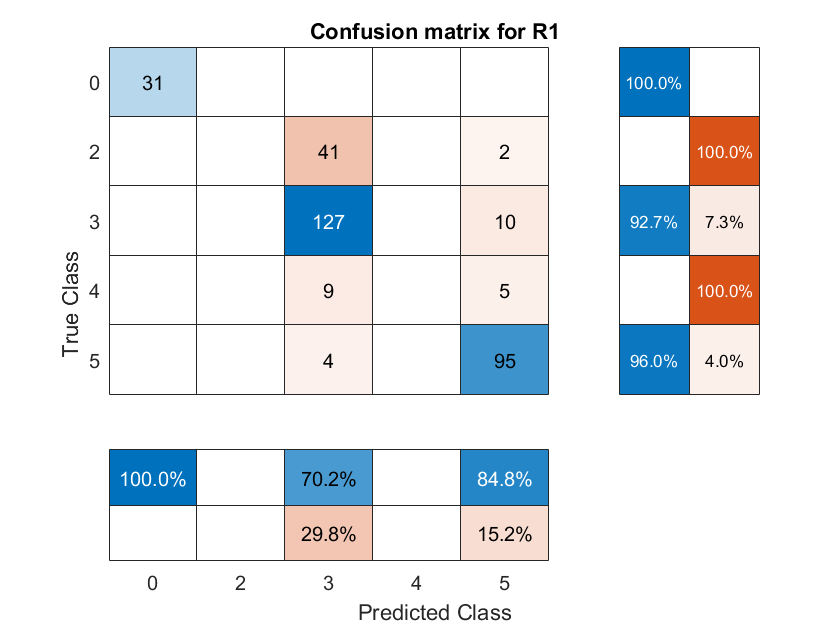

confusionMatrix(knownStages, 1, R1_prediction)

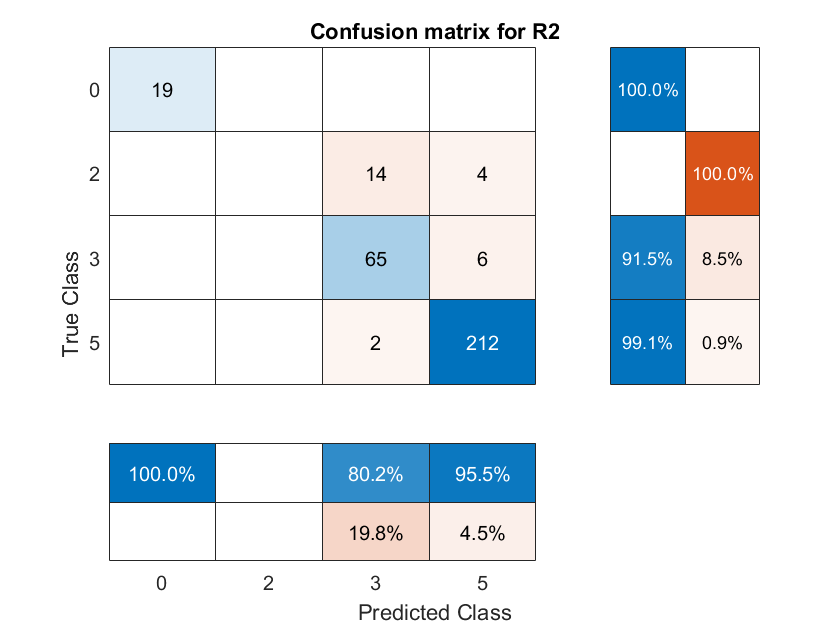

confusionMatrix(knownStages, 2, R2_prediction)

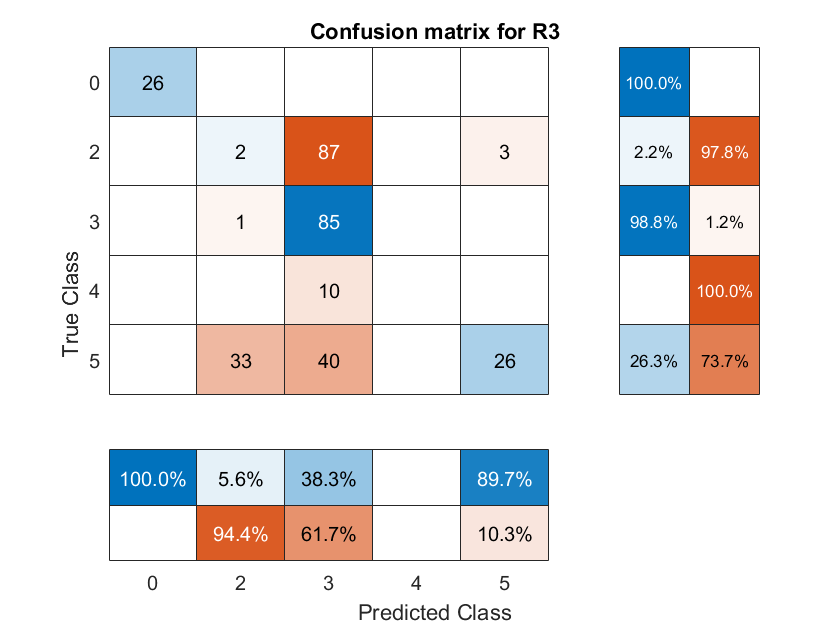

confusionMatrix(knownStages, 3, R3_prediction)

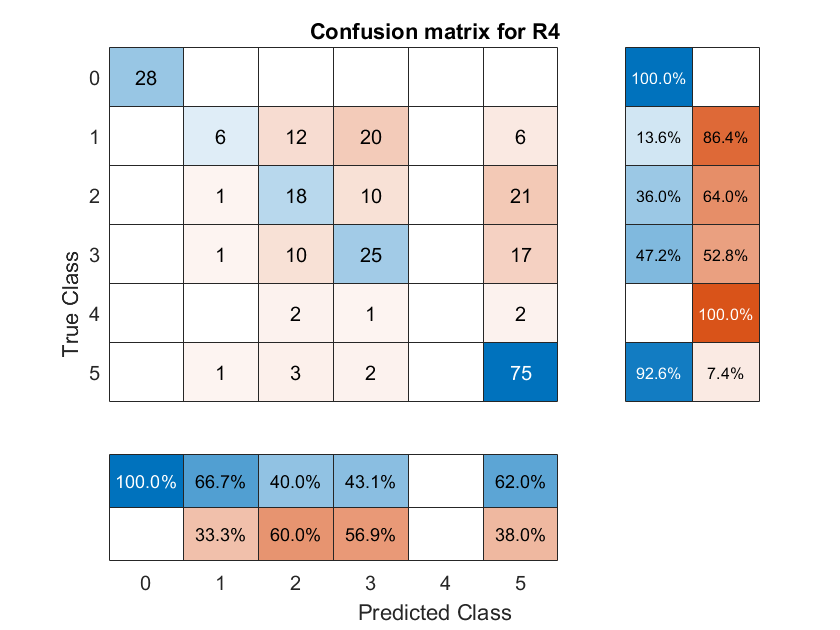

confusionMatrix(knownStages, 4, R4_prediction)

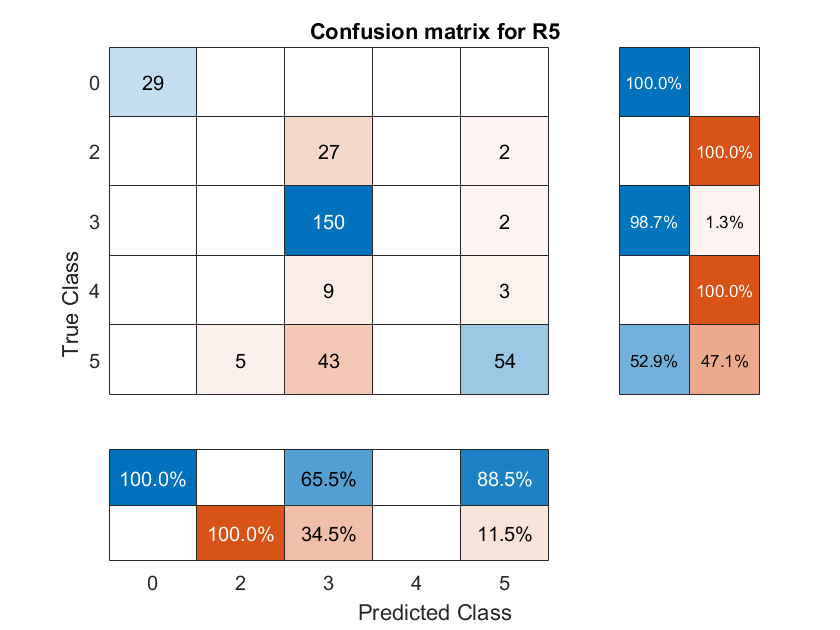

confusionMatrix(knownStages, 5, R5_prediction)